% Create a synthetic image with a known sub-pixel peak
[X, Y] = meshgrid(1:0.1:10, 1:0.1:10);
img = exp(-((X - 5.3).^2 + (Y - 5.7).^2) / (2 * 0.5^2));

% Downsample to a coarser grid
imgCoarse = imresize(img, [20, 20], 'bilinear');

% Compute sub-pixel maximum
[subRow, subCol, maxVal] = subpixelMax2D(imgCoarse);

% Display results
fprintf('Sub-pixel maximum at (row, col): (%.3f, %.3f) with value %.4f\n', ...
        subRow, subCol, maxVal);

Sub-pixel maximum at (row, col): (10.948, 10.052) with value 0.8396


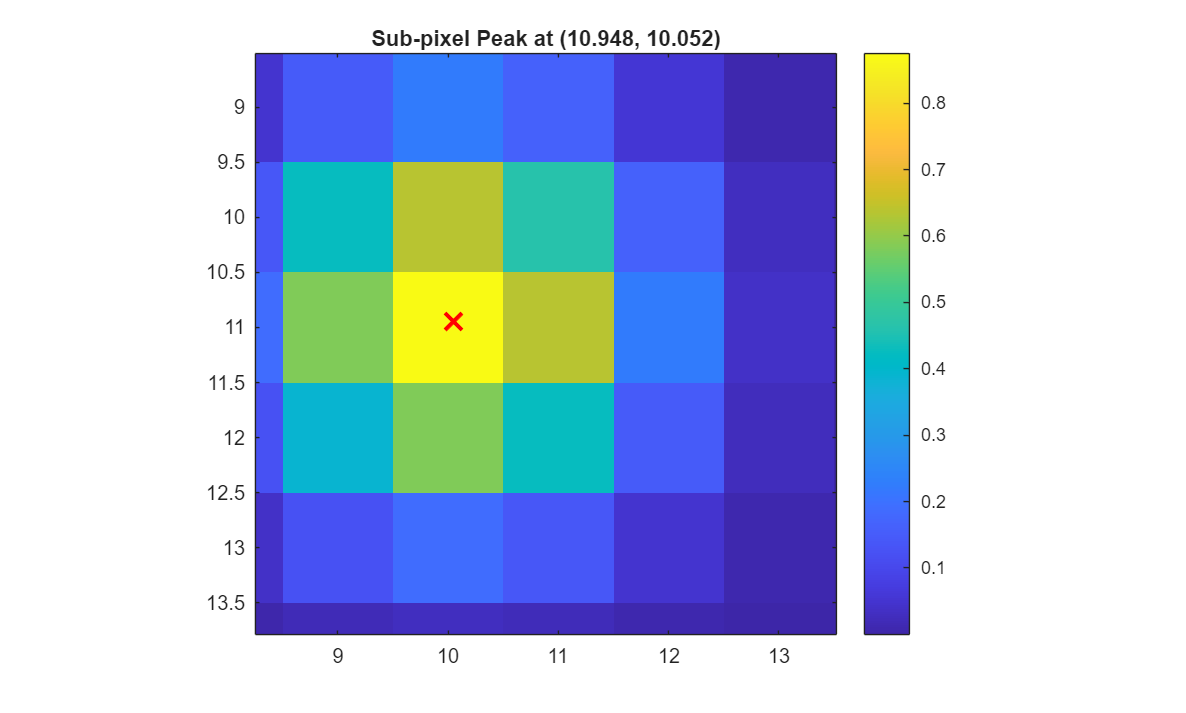


% Visualization
figure; imagesc(imgCoarse); axis image; colorbar;
hold on; plot(subCol, subRow, 'rx', 'MarkerSize', 12, 'LineWidth', 2);
title(sprintf('Sub-pixel Peak at (%.3f, %.3f)', subRow, subCol));


function [subRow, subCol, maxVal] = subpixelMax2D(img)
% SUBPIXELMAX2D Finds sub-pixel maximum in a 2D image using quadratic fitting.
%   [subRow, subCol, maxVal] = subpixelMax2D(img)
%   Inputs:
%       img - 2D image matrix
%   Outputs:
%       subRow, subCol - sub-pixel coordinates of maximum
%       maxVal - interpolated maximum value at sub-pixel location

    % Ensure input is double for calculations
    img = double(img);

    % Step 1: Find integer location of max pixel
    [~, linearIdx] = max(img(:));
    [rMax, cMax] = ind2sub(size(img), linearIdx);

    % Check for border conditions (use a 3x3 neighborhood)
    if rMax <= 1 || rMax >= size(img,1) || cMax <= 1 || cMax >= size(img,2)
        warning('Maximum is on the border; sub-pixel accuracy limited.');
        subRow = rMax;
        subCol = cMax;
        maxVal = img(rMax, cMax);
        return;
    end

    % Step 2: Extract 3x3 neighborhood
    neighborhood = img(rMax-1:rMax+1, cMax-1:cMax+1);

    % Step 3: Create design matrix for 2D quadratic fit
    [X, Y] = meshgrid(-1:1, -1:1);
    X = X(:); Y = Y(:); Z = neighborhood(:);
    M = [X.^2, Y.^2, X.*Y, X, Y, ones(size(X))];

    % Step 4: Least squares solution for coefficients
    coeffs = M \ Z;
    a = coeffs(1); b = coeffs(2); c = coeffs(3);
    d = coeffs(4); e = coeffs(5);

    % Step 5: Solve for sub-pixel maximum (critical point of the quadratic)
    A = [2*a, c; c, 2*b];
    B = -[d; e];

    if rank(A) < 2
        warning('Degenerate quadratic fit. Returning integer maximum.');
        subPixelOffset = [0; 0];
    else
        subPixelOffset = A \ B; % [dx; dy]
    end

    % Ensure offsets are within one pixel
    subPixelOffset = max(min(subPixelOffset, 1), -1);

    % Step 6: Compute sub-pixel coordinates
    subRow = rMax + subPixelOffset(2);
    subCol = cMax + subPixelOffset(1);

    % Step 7: Interpolated max value at sub-pixel location
    maxVal = coeffs(6) + ...
             d * subPixelOffset(1) + e * subPixelOffset(2) + ...
             a * subPixelOffset(1)^2 + ...
             b * subPixelOffset(2)^2 + ...
             c * subPixelOffset(1) * subPixelOffset(2);

end
